# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 28-Mar-2022 20:52:20

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([13 1842 1],"Name","imageinput","Normalization","none")
    convolution2dLayer([7 7],64,"Name","conv_1","Padding","same","Stride",[2 2])
    maxPooling2dLayer([3 3],"Name","maxpool","Padding",[1 1 1 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","conv_2","Padding","same")
    convolution2dLayer([3 3],64,"Name","conv_3","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","conv_4","Padding","same")
    convolution2dLayer([3 3],64,"Name","conv_5","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","conv_6","Padding","same")
    convolution2dLayer([3 3],64,"Name","conv_7","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_3")
    convolution2dLayer([3 3],128,"Name","conv_8","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv_9","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","conv_10","Padding","same")
    convolution2dLayer([3 3],128,"Name","conv_11","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","conv_12","Padding","same")
    convolution2dLayer([3 3],128,"Name","conv_13","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","conv_14","Padding","same")
    convolution2dLayer([3 3],128,"Name","conv_15","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_6")
    convolution2dLayer([3 3],256,"Name","conv_16","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","conv_17","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","conv_18","Padding","same")
    convolution2dLayer([3 3],256,"Name","conv_19","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_7");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","conv_20","Padding","same")
    convolution2dLayer([3 3],256,"Name","conv_21","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_8");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","conv_22","Padding","same")
    convolution2dLayer([3 3],256,"Name","conv_23","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_9");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","conv_24","Padding","same")
    convolution2dLayer([3 3],256,"Name","conv_25","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_10");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","conv_26","Padding","same")
    convolution2dLayer([3 3],256,"Name","conv_27","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_11")
    convolution2dLayer([3 3],512,"Name","conv_28","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv_29","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],512,"Name","conv_30","Padding","same")
    convolution2dLayer([3 3],512,"Name","conv_31","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_12");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],512,"Name","conv_32","Padding","same")
    convolution2dLayer([3 3],512,"Name","conv_33","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_13")
    averagePooling2dLayer([1 1],"Name","avgpool2d","Padding","same")
    fullyConnectedLayer(1000,"Name","fc_1")
    fullyConnectedLayer(6,"Name","fc_2")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"maxpool","conv_2");
lgraph = connectLayers(lgraph,"maxpool","addition_1/in2");
lgraph = connectLayers(lgraph,"conv_3","addition_1/in1");
lgraph = connectLayers(lgraph,"addition_1","conv_4");
lgraph = connectLayers(lgraph,"addition_1","addition_2/in1");
lgraph = connectLayers(lgraph,"conv_5","addition_2/in2");
lgraph = connectLayers(lgraph,"addition_2","conv_6");
lgraph = connectLayers(lgraph,"addition_2","addition_3/in1");
lgraph = connectLayers(lgraph,"conv_7","addition_3/in2");
lgraph = connectLayers(lgraph,"conv_9","conv_10");
lgraph = connectLayers(lgraph,"conv_9","addition_4/in1");
lgraph = connectLayers(lgraph,"conv_11","addition_4/in2");
lgraph = connectLayers(lgraph,"addition_4","conv_12");
lgraph = connectLayers(lgraph,"addition_4","addition_5/in1");
lgraph = connectLayers(lgraph,"conv_13","addition_5/in2");
lgraph = connectLayers(lgraph,"addition_5","conv_14");
lgraph = connectLayers(lgraph,"addition_5","addition_6/in1");
lgraph = connectLayers(lgraph,"conv_15","addition_6/in2");
lgraph = connectLayers(lgraph,"conv_17","conv_18");
lgraph = connectLayers(lgraph,"conv_17","addition_7/in1");
lgraph = connectLayers(lgraph,"conv_19","addition_7/in2");
lgraph = connectLayers(lgraph,"addition_7","conv_20");
lgraph = connectLayers(lgraph,"addition_7","addition_8/in1");
lgraph = connectLayers(lgraph,"conv_21","addition_8/in2");
lgraph = connectLayers(lgraph,"addition_8","conv_22");
lgraph = connectLayers(lgraph,"addition_8","addition_9/in2");
lgraph = connectLayers(lgraph,"conv_23","addition_9/in1");
lgraph = connectLayers(lgraph,"addition_9","conv_24");
lgraph = connectLayers(lgraph,"addition_9","addition_10/in1");
lgraph = connectLayers(lgraph,"conv_25","addition_10/in2");
lgraph = connectLayers(lgraph,"addition_10","conv_26");
lgraph = connectLayers(lgraph,"addition_10","addition_11/in1");
lgraph = connectLayers(lgraph,"conv_27","addition_11/in2");
lgraph = connectLayers(lgraph,"conv_29","conv_30");
lgraph = connectLayers(lgraph,"conv_29","addition_12/in1");
lgraph = connectLayers(lgraph,"conv_31","addition_12/in2");
lgraph = connectLayers(lgraph,"addition_12","conv_32");
lgraph = connectLayers(lgraph,"addition_12","addition_13/in1");
lgraph = connectLayers(lgraph,"conv_33","addition_13/in2");

## Plot Layers

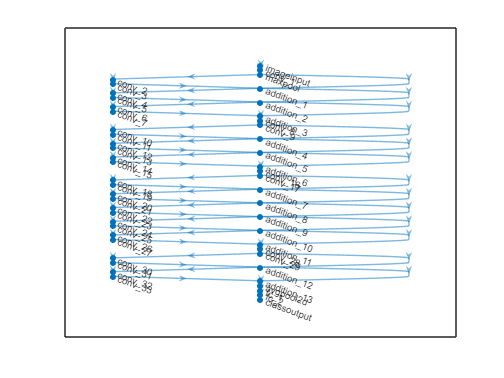

plot(lgraph);